# Day 6 - Initial Data Visualizations

[lr_accel, lr_gyro] = parsePowerSenseData_1('12inchtest_90bpm.csv');

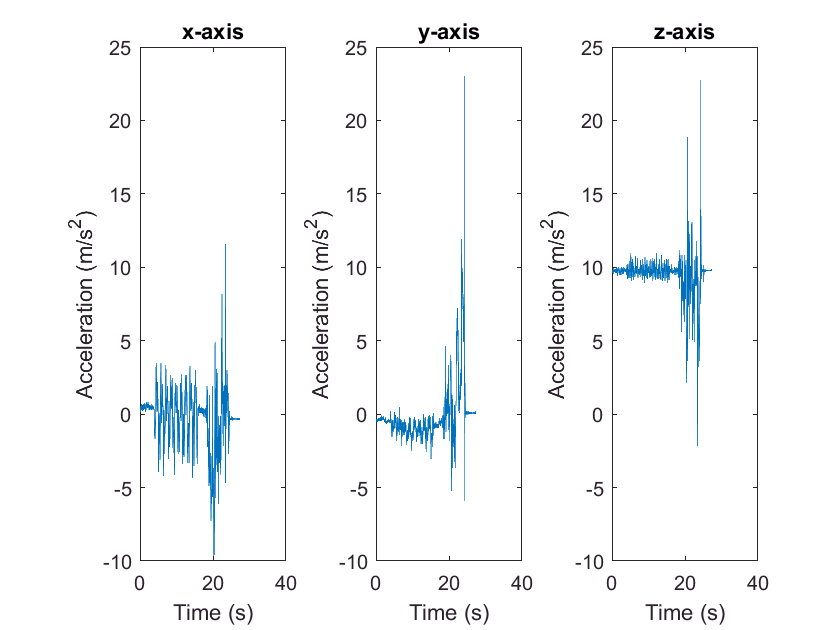

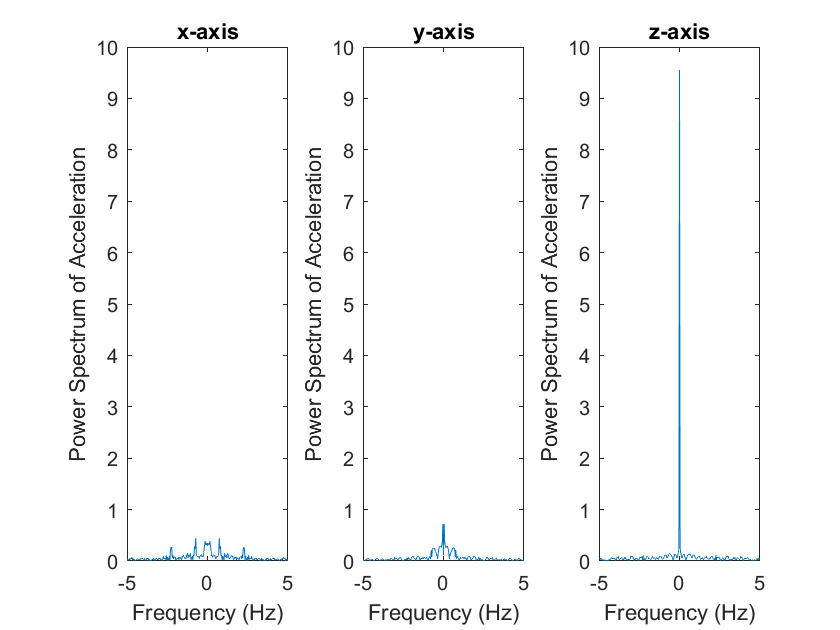

makeAccelerometerPlots(lr_accel,[],true)

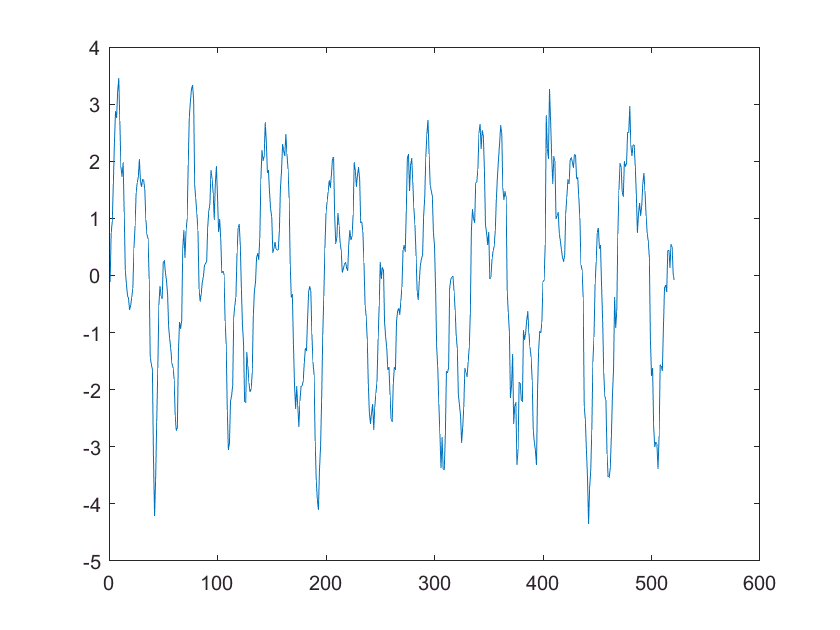

startcut = 280;
endcut = 800;

x_accel = lr_accel(:,2);
x_accel = x_accel(startcut:endcut);
plot(x_accel)

fft_x = real(fft(x_accel));
[~, i] = max(fft_x)

i = 24

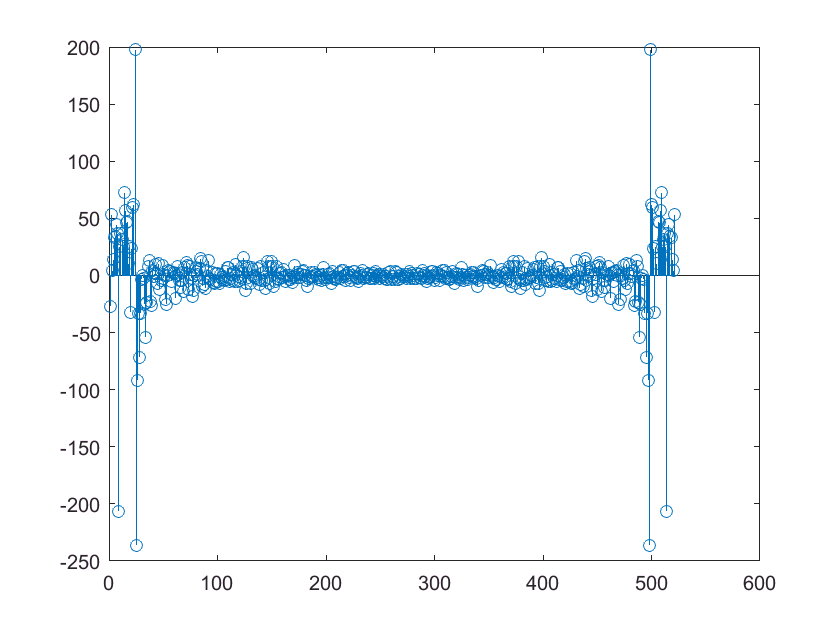

stem(fft_x)

Fs = 1/lr_accel(2,1)-(lr_accel(1,1));
% make_freq_plot(x_accel, Fs)

freq = -6.9475e+07

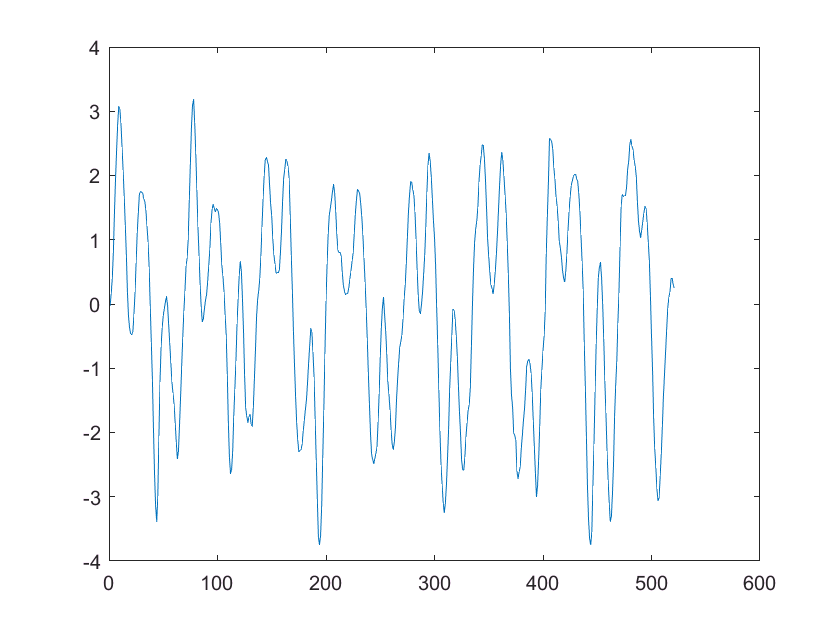



h = [1/4 1/4 1/4 1/4];          % moving average shape
x_accel = conv(x_accel, h);     % moving average convolution
x_accel = x_accel(1:(end-length(h)+1));  % adjusting for conv
x_times = lr_accel(:,1);        % grab times column
x_times = x_times(startcut:endcut);     % cutoff bad data
x_times = x_times-x_times(1);   % center unex times

figure
plot(x_accel)

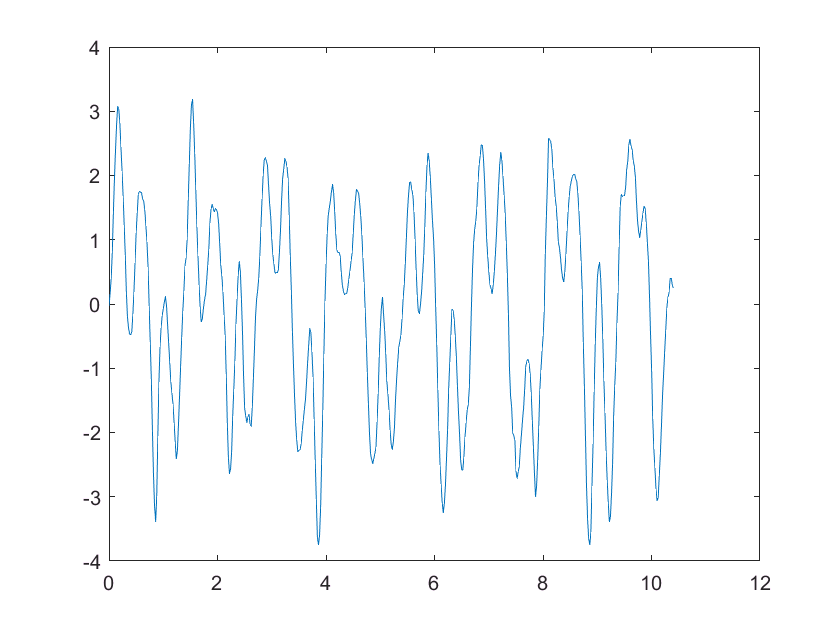

plot(x_times, x_accel)      